# **UCSC ECE 103 Signals and Systems**

**This live script covers basic functions and functions to familiarize with programming in MATLAB**

**Useful commands:**

clc   %Clear Command Window
clear all %Clear all variables in Workspace
close all % Close all windows (i.e figures, program outputs,etc)
% Recommended to add commands above at the beginning of file when running
% the full script

**Additional Commands:**

Ctrl + R  = Comment

Ctrl + T  = Uncomment

### Basics with MATLAB

a = 1

a = 1

b = 4e2  %e for scientific notation  4e2 == 400

b = 400

c = 3 ;  %Semicolon hides the output from the command window

%Data Types
rn = 5678.92347

rn = 5.6789e+03

rn_int = int32(rn)  

rn_int = int32
5679


sum_ab = a+b  %Math

sum_ab = 401

e = exp(a)

e = 2.7183

d = sqrt(b)

d = 20


whos a %Display characteristics of variable (size,type,attributes)

  Name      Size            Bytes  Class     Attributes

  a         1x1                 8  double              



help sqrt

 sqrt   Square root.
    sqrt(X) is the square root of the elements of X. Complex 
    results are produced if X is not positive.
 
    See also sqrtm, realsqrt, hypot.

    Documentation for sqrt
    Other functions named sqrt



help conv

 conv Convolution and polynomial multiplication.
    C = conv(A, B) convolves vectors A and B.  The resulting vector is
    length MAX([LENGTH(A)+LENGTH(B)-1,LENGTH(A),LENGTH(B)]). If A and B are
    vectors of polynomial coefficients, convolving them is equivalent to
    multiplying the two polynomials.
 
    C = conv(A, B, SHAPE) returns a subsection of the convolution with size
    specified by SHAPE:
      'full'  - (default) returns the full convolution,
      'same'  - returns the central part of the convolution
                that is the same size as A.
      'valid' - returns only those parts of the convolution 
                that are computed without the zero-padded edges. 
                LENGTH(C)is MAX(LENGTH(A)-MAX(0,LENGTH(B)-1),0).
 
    Class support for inputs A,B: 
       float: double, single
 
    See also deconv, conv2, 

### Vector, Matrices & Arrays

Matrix A  = (m,n) 

m = row 

n = column

% Make random, all ones, all zeros arrays,diagonal matrix
rand(3,3)

ans =     0.9649    0.9572    0.1419
    0.1576    0.4854    0.4218
    0.9706    0.8003    0.9157


ones(3,3)

ans =      1     1     1
     1     1     1
     1     1     1


zeros(3,3)

ans =      0     0     0
     0     0     0
     0     0     0


eye(3)

ans =      1     0     0
     0     1     0
     0     0     1




%Matrices and Vectors
a = [ 1 2 3; 4 5 6; 7 8 9]

a =      1     2     3
     4     5     6
     7     8     9


a(1,3)   %Refers to the row 1 column 3 == number 3

ans = 3


%Colon(:) Iterator
iterator = 1:10
iterator_coarse = 1:0.1:1

v1 = a(:,3)  %make vector will all elements of 3th column

v1 =      3
     6
     9


v2 = a(3,:)  %make vector will all elements of 3th row

v2 =      7     8     9


v3 = a(:, 1:2) %make vector will all elements of column 1 and 2

v3 =      1     2
     4     5
     7     8


### For / While Loops

iterator =      1     2     3     4     5     6     7     8     9    10


iterator_coarse =     1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000


% Multiply variable from 1 to 5
a=1 ;
initValue = 1;
endValue = 5;
for i= initValue:endValue
    product = a*i;
    fprintf('value of product: %d\n', product)
end

value of product: 1
value of product: 2
value of product: 3
value of product: 4
value of product: 5



%While Loop
i=1;
% while loop execution 
while( i <= endValue )
   product = a*i;
   fprintf('value of product: %d\n', product)
   i = i + 1;
end

value of product: 1
value of product: 2
value of product: 3
value of product: 4
value of product: 5


### If / Else statements

a = 10;
% check the condition using if statement 
   if a < 20 
   % if condition is true then print the following 
        fprintf('a is less than 20\n' );
%    elif a==10

a is less than 20


%         fprintf('value of a is : %d\n', a);
   else
        fprintf('value of a is : %d\n', a);
   end


value of a is : 10


### Plotting Tutorial

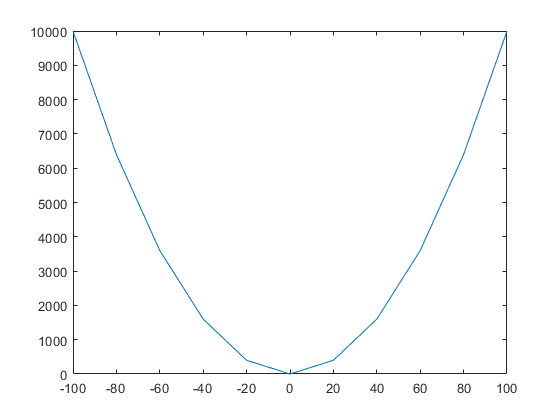

%Plotting Tutorial
figure() %Call new Figure
x = [1 2 3 4 5 6 7 8 9 10];
x = [-100:20:100];
y = x.^2;
plot(x, y)

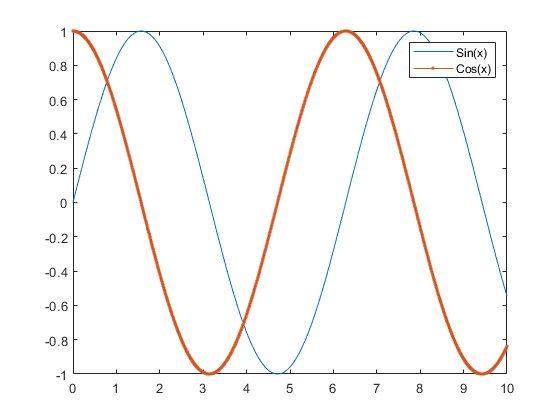

%Multiple functions in one Graph
figure()
x = [0 : 0.01: 10];
y = sin(x);
g = cos(x);
plot(x, y, x, g, '.-'), legend('Sin(x)', 'Cos(x)')

%Two Graphs in one Figure
figure()
x = [0:0.01:5];
y = exp(-1.5*x).*sin(10*x);
subplot(1,2,1)
plot(x,y), xlabel('x'),ylabel('exp(–1.5x)*sin(10x)'),axis([0 5 -1 1])
y = exp(-2*x).*sin(10*x);
subplot(1,2,2)

#### More Information:

[https://www.tutorialspoint.com/matlab/index.htm](https://www.tutorialspoint.com/matlab/index.htm)

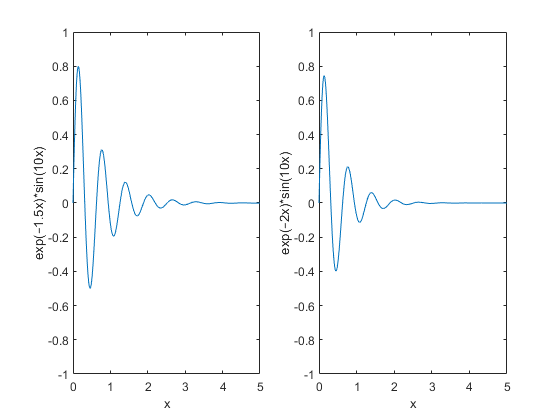

plot(x,y),xlabel('x'),ylabel('exp(–2x)*sin(10x)'),axis([0 5 -1 1])